# **Esercitazione 1 - ECG**

Obiettivo 1: implementare una funzione per identificare i picchi R all'interno di ciascun segnale.

load("data.mat")

Caricamento del dato nel workspace utilizzando la funzione `load().`

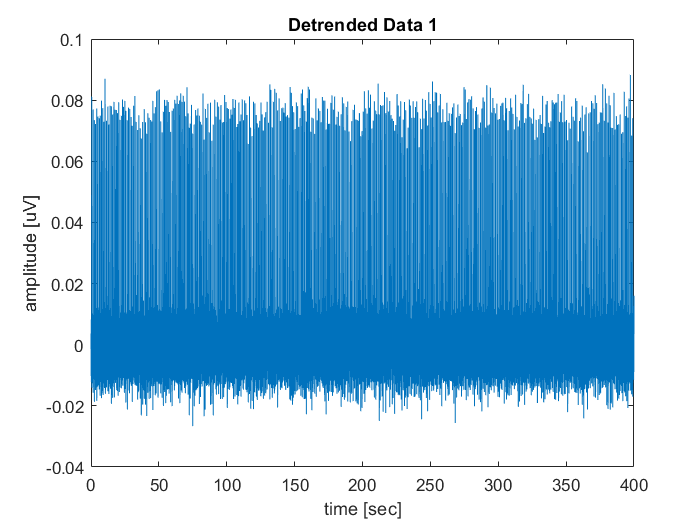

%lunghezza k delle finestre 
k = 1; % [s]

%suddivisione dei segnali
data1 = reshape(data1,fs*k,[]);
data1NoTrend = detrend(data1);

data2 = reshape(data2,fs*k,[]);
data2NoTrend = detrend(data2);

%visualizzazione del risultato ottenuto
data1NoTrend = data1NoTrend(:);

data2NoTrend = data2NoTrend(:);

figure, plot(time,data1NoTrend)
title('Detrended Data 1')
ylabel('amplitude [uV]')
xlabel('time [sec]')

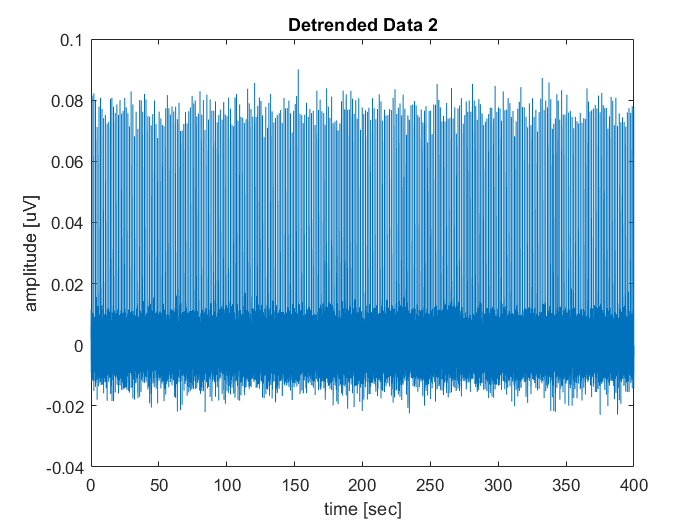


%hold on
%plot(mean(data1NoTrend),"r", "LineWidth",5)
%hold off

figure, plot(time,data2NoTrend)
title('Detrended Data 2')
ylabel('amplitude [uV]')
xlabel('time [sec]')

Suddivisione del segnale in finestre continue con stessa lunghezza pari a pochi secondi (scelti arbitrareamente) e quindi rimozione del trend lineare tramite l'uso della funzione detrend.

%function thr = find_thr(data1,  )

Funzione per il calcolo della soglia ottima.

thr=find_thr(data1NoTrend,7.5)

thr = 0.0555

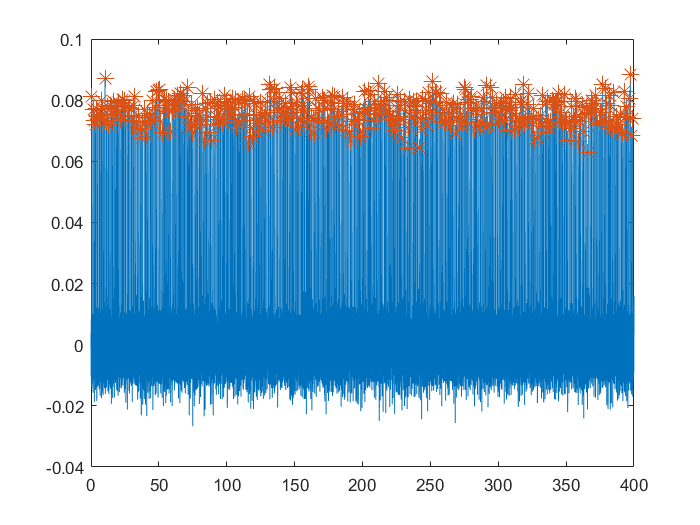

[values,MaxInd] = findpeaks(data1NoTrend,fs,'MinPeakHeight',  thr);
figure

plot(time, data1NoTrend)
hold on
plot(MaxInd,values,'*','MarkerSize',10)

%scatter(time(MaxInd),data1NoTrend(MaxInd), [], "red", "filled")]


Identificazione di tutti i picchi R data una soglia ottima.

Obiettivo 2: implementare una funzione compute_heart_rate per stimare la frequenza del battito cardiaco.

%function heart_rate = compute_heart_rate(input)

Obiettivo 3: implementare una funzione per il calcolo della durata del complezzo QRS e per la visualizzazione del complesso QRS medio.

%MaxInd = vettore con gli indici dei picchi

dist_tra_picchi=MaxInd(2 : end, :)-MaxInd(1 : end-1, :);clc

dist_media=ceil(mean(disttrapicchi));

Unrecognized function or variable 'disttrapicchi'.


meta_dist=ceil(distmedia/2);
 
%matrice che contiene i singoli tracciati
solo_tracciato=zeros(2*metadist+1, length(MaxInd));

for j=1:length(MaxInd) 
solo_tracciato (:, j ) = dataNoTrend ( (MaxInd(j)-metadist) : (MaxInd(j)+metadist) ) ;
end

solo_tracciato=solo_tracciato';

solo_medio=mean(solo_tracciato);

figure
plot(1:2*metadist+1,solo_medio);


Obiettivo 4: implementare una funzione per la stima della densità di probabilità delle variabili derivate da ECG per descrivere i ritmi cardiaci.

...

Istogramma delle variabili derivate dall'ECG per entrambi i ritmi cardiaci.